# **xEV Battery State-of-Charge Estimator using a Feedforward Deep Neural Network**

## The objective of this code is to present the training process of an SOC estimator using a  Feedforward Deep Neural Network (FNN) approach. 

**Abstract**

Battery state-of-charge (SOC) is critical information for the vehicle energy management system and must be accurately estimated to ensure reliable and affordable electrified vehicles (xEV). However, due to the nonlinear temperature, health, and SOC dependent behaviour of Li-ion batteries, SOC estimation is still a significant automotive engineering challenge. Traditional approaches to this problem, such as electrochemical models, usually require precise parameters and knowledge from the battery composition as well as its physical response. In contrast, neural networks are a data-driven approach that requires minimal knowledge of the battery or its nonlinear behaviour. The objective of this work is to present the design process of an SOC estimator using a deep feedforward neural network (FNN) approach. The method includes a description of data acquisition, data preparation, development of an FNN, FNN tuning,  and robust validation of the FNN to sensor noise. To develop a robust estimator, the FNN was exposed, during training, to datasets with errors intentionally added to the data, e.g. adding cell voltage variation of ±4mV, cell current variation of ±110mA, and temperature variation of ±5⁰C. The error values were chosen to be similar to the noise and error obtained from real sensors used in commercially available xEVs.  The robust FNN trained from two Li-ion cells datasets, one for a nickel manganese cobalt oxide (NMC) cell and the second for a nickel cobalt aluminum oxide (NCA) chemistry cell, is shown to overcome the added errors and obtain a SOC estimation accuracy of 1% root mean squared error (RMSE).

**Instructions for Downloading and Running the Script**

- Select download all files from the Mendeley Data page ([https://data.mendeley.com/datasets/cp3473x7xv/2](https://data.mendeley.com/datasets/cp3473x7xv/2)).  

- The files will be downloaded as a zip file.  Unzip the file to a folder, do not modify the folder structure.  

- Navigate to the folder with "FNN_xEV_Li_ion_SOC_EstimatorScript_March_2020.mlx"

- Open and run "FNN_xEV_Li_ion_SOC_EstimatorScript_March_2020.mlx"

- The matlab script should run without any modification, if there is an issue it's likely due to the testing and training data not being in the expected place.

- The script is set by default to train for 50 epochs and to repeat the training 3 times.  This should take 5-10 minutes to execute.

- To recreate the results in the paper, set number of epochs to 5500 and number of repetitions to 10.

Script used as part of: C. Vidal, P. Kollmeyer, M. Naguib, P. Malysz, O. Gross, and A. Emadi, “Robust xEV Battery State-of-Charge Estimator Design using Deep Neural Networks,” *in Proc* *WCX SAE World Congress Experience*, Detroit, MI, Apr, 2020  

 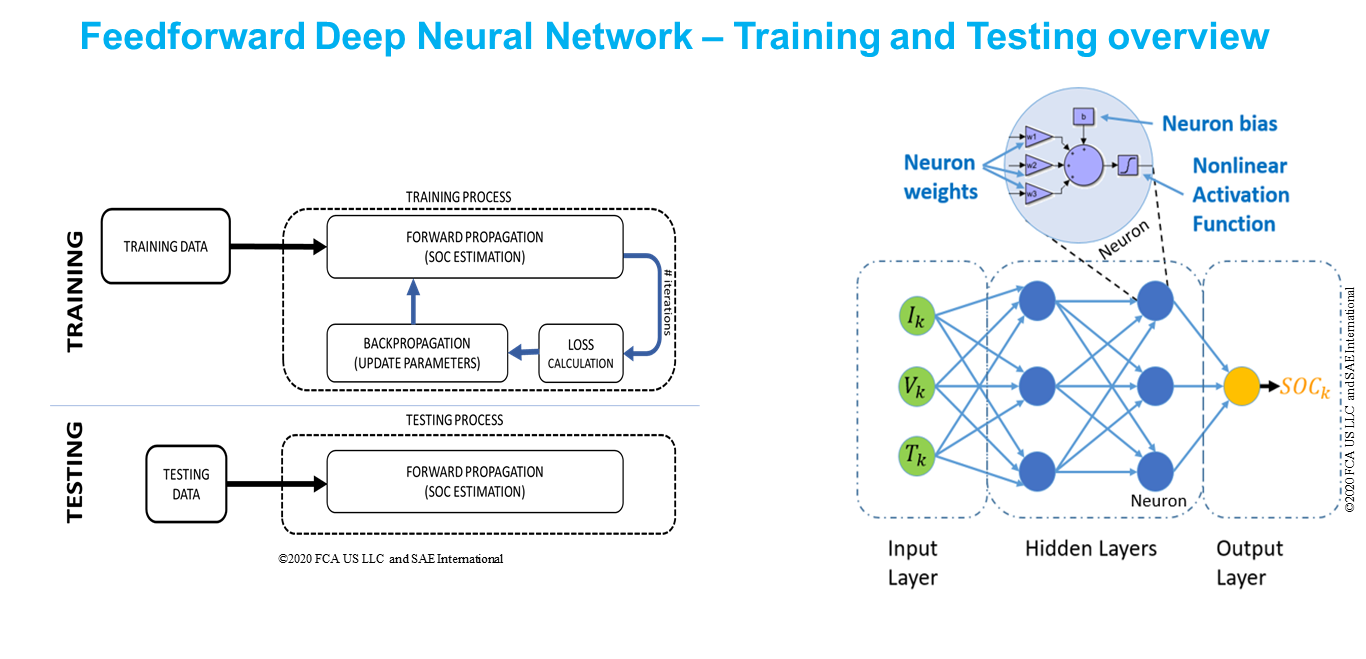

clc;
close all;
clearvars;
fclose all;

**Add the Dataset File name**

Replace "**FileName.zip**" by the file name you want to use. Note: The zip file need to have "**Train**"  and "**Test**" separate folders

filename ="LG_HG2_Prepared_Dataset_McMasterUniversity_Jan_2020\LGHG2@n10C_to_25degC.zip"; % Add the Dataset File name
outputFolder = fullfile(tempdir,"LGHG2@n10C_to_25degC");% The temporary location and name where the training data unzipped
unzip(filename,outputFolder); 

**Add the location** in ('...') where the data of each iteration will be stored as it will save multiple models at each epoch (see"CheckpointPath" on the training parameter);

mkdir("Data folder")

NET_Path="Data folder";
%slect the Datafolder created in the next popup window to allow storing the
%the data each iteration
NET_Path=uigetdir('','Select folder to store data from each training iteration'); 

# Create Datastore datasets - Training and Testing

## Necessary when working with large collections of data

####  (Check Matlab Help for "datastore")

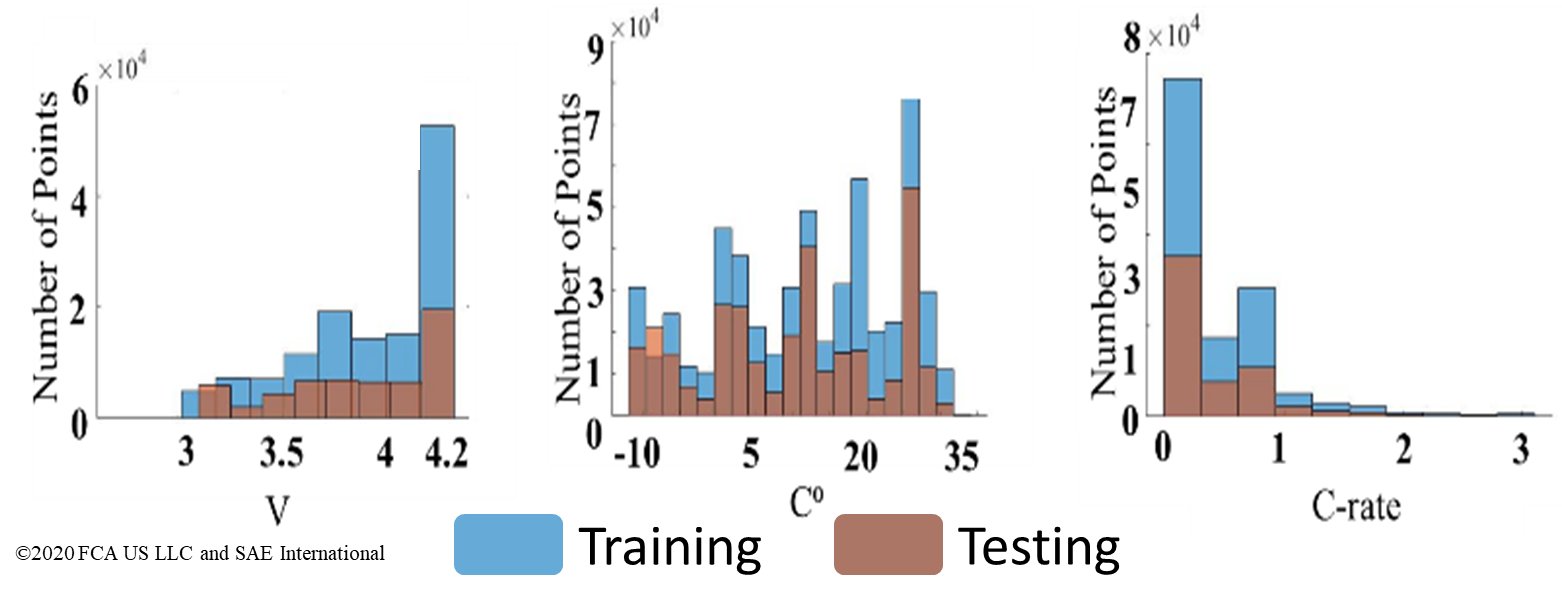

(a) Histogram of the battery voltage (V), (b) temperature (C⁰), and (c) current (C-rate) from training and testing datasets from the LG_HG2 cell

folderTrain = fullfile(outputFolder,"Train");
fdsPredictorTrain = fileDatastore(folderTrain, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);  %Is a datastore, for the training dataset, which is a repository for collections of data that are too large to fit in memory. 

folderTest = fullfile(outputFolder,"Test");
fdsPredictorTest = fileDatastore(folderTest, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true); % Is a datastore, for the Testing dataset, which is a repository for collections of data that are too large to fit in memory 

preview(fdsPredictorTrain)

ans = struct with fields:
    X: [5×669956 double]
    Y: [0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 … ]


preview(fdsPredictorTest)

ans = struct with fields:
    X: [5×39293 double]
    Y: [1 1.0000 1.0000 1.0000 1.0000 1.0000 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9998 0.9998 0.9998 0.9998 0.9998 0.9998 0.9997 0.9996 0.9994 0.9991 0.9989 0.9988 0.9987 0.9983 0.9982 0.9980 0.9980 0.9980 … ]



folderYTrain = fullfile(outputFolder,"Train");
fdsObjectiveTrain = fileDatastore(folderYTrain, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);% Is a datastore for the objective function, in this case SOC reference data for the training dataset. 

folderYTest = fullfile(outputFolder,"Test");
fdsObjectiveTest = fileDatastore(folderYTest, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);% Is a datastore for the objective function, in this case SOC reference data for the testing dataset. 

 preview(fdsObjectiveTrain);
% preview(fdsObjectiveTest);

## Transform and Combine Data set 

RR=readall(fdsPredictorTrain);    % read all training data files
numObservations = numel(RR);
for i=1:numObservations
    sequence = RR{i};  %combine training data set files into one structure. 
    sequenceLengths(i) = size(sequence.X,2);
end

# Mini-Batch Size

NumberOfMinibatches = 1; % If the dataset doesn't fit the memmory it'e necessary to increase the number of MiniBatches. Need to be a integer number 1 or >1.
miniBatchSize = round(numObservations/NumberOfMinibatches) % Size of Mini-batches 

miniBatchSize = 1

sequenceLength = max(sequenceLengths)%Max length of the training dataset files if the files are not in the same length, this will determine the amount of padding on the shorter files. If all files have the same lenght, there will be no padding .

sequenceLength = 669956

RRR=readall(fdsPredictorTest); % read all Test data files
numObservationsY = numel(RRR); 
for i=1:numObservationsY
    sequence = RRR{i}; %Combine Test data set files into one structure.
    sequenceLengthsY(i) = size(sequence.X,2);
end
sequenceLengthY= max(sequenceLengthsY) %Max length of the objective function of the training dataset (SOC or Ah)

sequenceLengthY = 47517

RRTest=readall(fdsPredictorTest);
numObservationsTest = numel(RRTest);

# Transforming Datastore dataset

Padding will be used if the files have different lengths, the padding function is set to repeat the last part of the shorter files to match the size of the longest file in the dataset (valid only when there are multiple files in the dataset). Is preferable to avoid as much padding as possible.

fdsObjectiveTrain = transform(fdsObjectiveTrain,@(data) padSequenceY(data,sequenceLength)); % Padding function - Objective function Training Dataset
fdsObjectiveTest = transform(fdsObjectiveTest,@(data) padSequenceY(data,sequenceLengthY)); % Padding function - Objective function Testing Dataset
ObjectiveTest=readall(fdsObjectiveTest); %Objective function Test dataset, this is only to help manipulate the dataset for ploting and calculate the Errors.

tdsTrain = transform(fdsPredictorTrain,@(data) padSequence(data,sequenceLength)); % Padding function - Training Dataset
tdsTest = transform(fdsPredictorTest,@(data) padSequence(data,sequenceLengthY));  % Padding function - Testing Dataset
preview(tdsTrain);
PredictorTest=readall(tdsTest);%Predictors test dataset 

To input both the predictors and Objectives from both datastores into a deep learning network, combine them using the `combine` function.

cdsTrain = combine(tdsTrain,fdsObjectiveTrain);
cdsTest = combine(tdsTest,fdsObjectiveTest);

Preview the combined datastore.  The first element corresponds to the "Predictors". The second element corresponds to the "Objective".

preview(cdsTrain)

ans = 1×2 cell array
    {5×669956 double}    {[0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 

# Validation dataset

V=1; % Selection of the Validation dataset, in this script the validation dataset is the same as Test dataset, but it can be changed 
X=PredictorTest{V}; %X predictors Validation dataset 
Y=ObjectiveTest{V}; % Objective function "Y == SOC" for the Validation dataset

# Define NN Network Architecture

Define the NN network architecture.  

## Specify NN training parameter

Number of outputs (**SOC**)

numResponses = 1;

Number of inputs features (**V, I, Temp, V_avg, I_avg**)

numFeatures = 5; 

Number of hidden units **'N'**, where each hidden unit for FNN represents a Neuron.

numHiddenUnits = 55; 

Number of **Epochs**

Epochs  =  50; 

Number of epochs for dropping the learning rate 

LearnRateDropPeriod = 1000; 

**Initial Learning rate**. Very important parameter

InitialLearnRate=0.01;

Factor for dropping the learning rate, ex.: reduce to 10% of the current learning rate at every 'LearnRateDropPeriod

LearnRateDropFactor=0.1; 

Validate the model at each Iterations when values is equal to 1.

validationFrequency = 10;  

Select the amount the training process will be repeated 

repeat=3;

# **FNN - Structure**

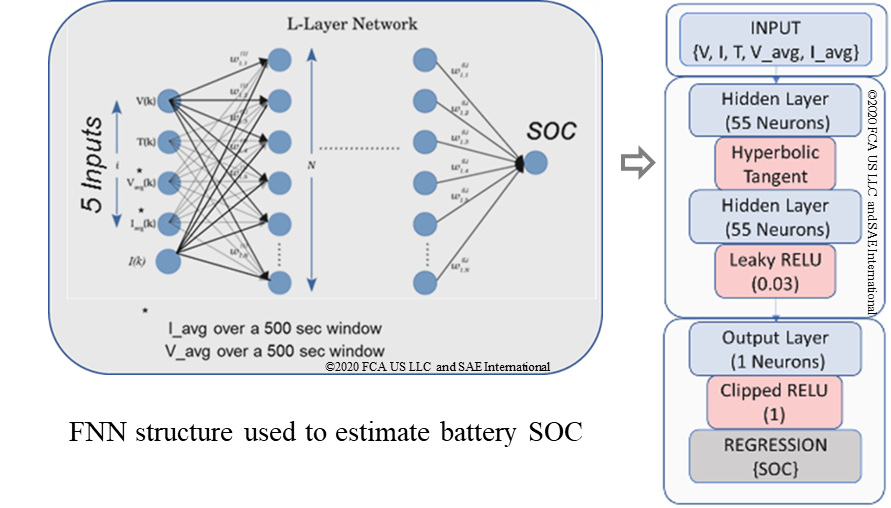

    layers = [sequenceInputLayer(numFeatures,"Normalization","zerocenter")
        fullyConnectedLayer(numHiddenUnits)
        tanhLayer                            % Hyperbolic Tangent
        fullyConnectedLayer(numHiddenUnits)
        leakyReluLayer(0.3)                  % The leaky rectified linear unit (ReLU) activation operation performs a nonlinear threshold operation, where any input value less than zero is multiplied by a fixed scale factor
        fullyConnectedLayer(numResponses)
        clippedReluLayer(1)                  % A clipped ReLU layer performs a threshold operation, where any input value less than zero is set to zero and any value above the clipping ceiling, this case '1', is set to that clipping ceiling.
        regressionLayer];
    
    options = trainingOptions('adam', ...                    % Adam optimizer
        'MaxEpochs',Epochs,'ExecutionEnvironment','cpu', ...% Select GPU if you works on computer with GPU
        'GradientThreshold',1, ...
        'InitialLearnRate',InitialLearnRate, ...
        'LearnRateSchedule','piecewise', ...
        'LearnRateDropPeriod',LearnRateDropPeriod, ...
        'LearnRateDropFactor',LearnRateDropFactor, ...
        'L2Regularization',1, ...
        'ValidationData', {X,Y}, ...
        'Shuffle','never',...
        "Verbose",1,...
        'ValidationFrequency',validationFrequency, ...
        'MiniBatchSize',miniBatchSize, ...
        'Plots','training-progress',...
        'CheckpointPath', NET_Path); % to save each trained model during the training process, if necessary it can be "commented-out" and will only the last model will be available to be save.

## Train the FNN network with the specified training options.

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |         0.66 |         0.61 |       0.2190 |       0.1861 |          0.0100 |
|      10 |          10 |       00:00:51 |         0.11 |         0.13 |       0.0056 |       0.0079 |          0.0100 |
|      20 |          20 |       00:01:27 |         0.06 |         0.09 |       0.0019 |       0.0039 |          0.0100 |
|      30 |          30 |       00:01:45 |         0.04 |         0.05 |       0.0008 |       0.0010 |          0.

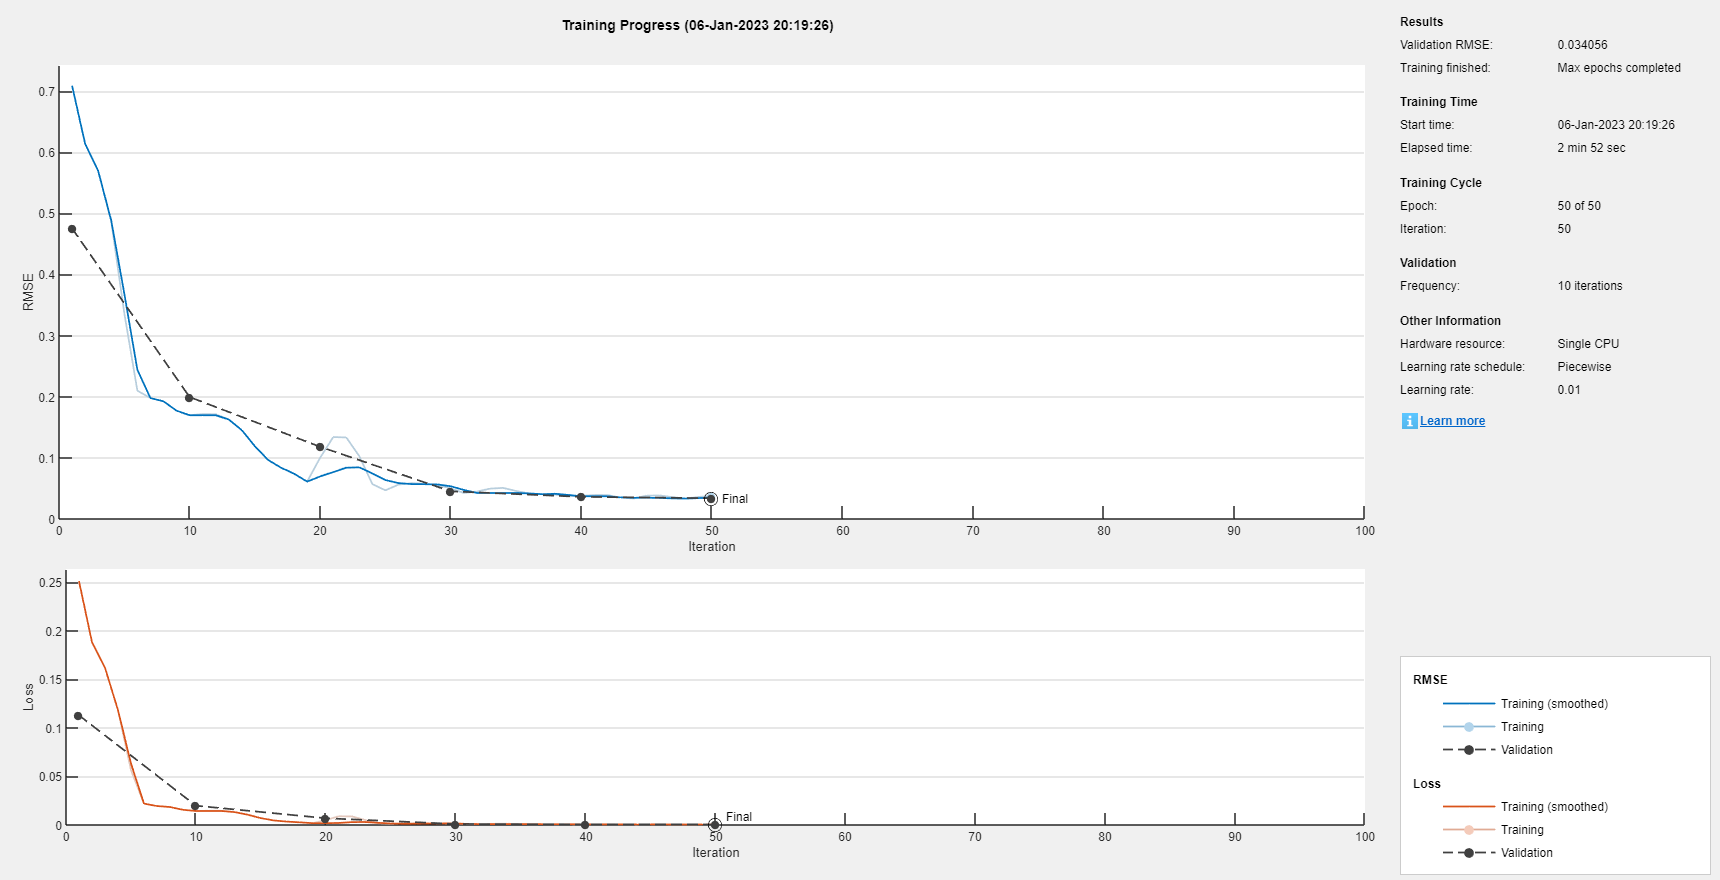

for i=1:repeat
    net = trainNetwork(cdsTrain,layers,options);

# **Test the Network**

**The following section is used to calcultae the MAX, MAE, RMS errors of the test dataset and to plot the corresponding SOC of Test dataset after the training process **

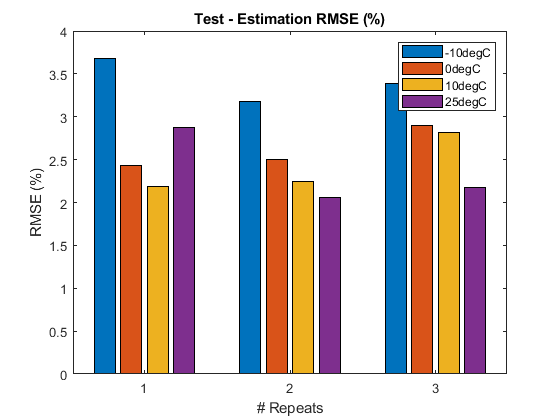

    N=50; % To remove the first 'N' and last 'NN' datapoints to compensate the lack of previous data, which wouldn't normally occur in a real life xEV application
    NN=50;
    
    YT=readall(fdsObjectiveTest);
    XT=readall(fdsPredictorTest);
    X_T=[];Y_Test=[];X_Test=[];Y_T=[];
    Error_Test=[];
    Nets{i} = net;% save the last trained model at the end of each repeat
    Y_Pred_n10degC = predict(net,XT{1, 1}.X,'MiniBatchSize',miniBatchSize);
    Y_Pred_0degC = predict(net,XT{2, 1}.X,'MiniBatchSize',miniBatchSize);

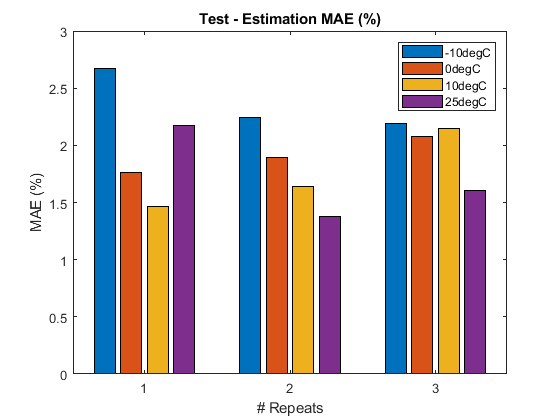

    Y_Pred_10degC = predict(net,XT{3, 1}.X,'MiniBatchSize',miniBatchSize);
    Y_Pred_25degC = predict(net,XT{4, 1}.X,'MiniBatchSize',miniBatchSize);
    
    Error_Test_n10degC = Y_Pred_n10degC(:,N:end-NN)-XT{1, 1}.Y(:,N:end-NN);
    Error_Test_0degC = Y_Pred_0degC(:,N:end-NN)-XT{2, 1}.Y(:,N:end-NN);
    Error_Test_10degC = Y_Pred_10degC(:,N:end-NN)-XT{3, 1}.Y(:,N:end-NN);

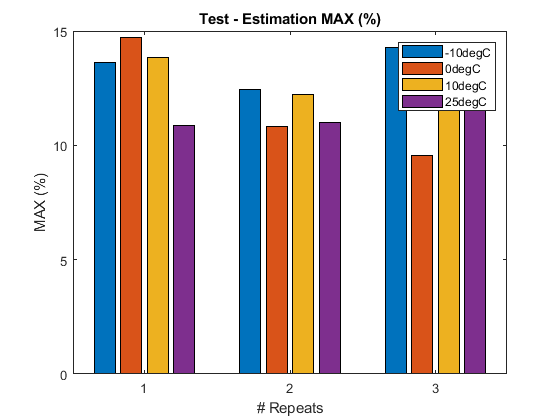

    Error_Test_25degC = Y_Pred_25degC(:,N:end-NN)-XT{4, 1}.Y(:,N:end-NN);
    
    E_Test_RMSE_n10degC{i} = sqrt(mean((Error_Test_n10degC).^2))*100; %SOC Test dataset root mean square error
    E_Test_MAE_n10degC{i} = mae(Error_Test_n10degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_n10degC{i} = max(abs(Error_Test_n10degC)*100); %max SOC error of Test dataset
    
    E_Test_RMSE_10degC{i} = sqrt(mean((Error_Test_10degC).^2))*100; %SOC Test dataset root mean square error

    E_Test_MAE_10degC{i} = mae(Error_Test_10degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_10degC{i} = max(abs(Error_Test_10degC)*100); %max SOC error of Test dataset
    
    E_Test_RMSE_0degC{i} = sqrt(mean((Error_Test_0degC).^2))*100; %SOC Test dataset root mean square error
    E_Test_MAE_0degC{i} = mae(Error_Test_0degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_0degC{i} = max(abs(Error_Test_0degC)*100); %max SOC error of Test dataset
    
    E_Test_RMSE_25degC{i} = sqrt(mean((Error_Test_25degC).^2))*100; %SOC Test dataset root mean square error
    E_Test_MAE_25degC{i} = mae(Error_Test_25degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_25degC{i} = max(abs(Error_Test_25degC)*100); %max SOC error of Test dataset

 end

RMSE_SUMMARY = ['-10degC_RMSE',E_Test_RMSE_n10degC;'0degC_RMSE',E_Test_RMSE_0degC;'10degC_RMSE',E_Test_RMSE_10degC;'25degC_RMSE',E_Test_RMSE_25degC];
MAE_SUMMARY = ['-10degC_MAE',E_Test_MAE_n10degC;'0degC_MAE',E_Test_MAE_0degC;'10degC_MAE',E_Test_MAE_10degC;'25degC_MAE',E_Test_MAE_25degC];
MAX_SUMMARY = ['-10degC_MAX',E_Test_MAX_n10degC;'0degC_MAX',E_Test_MAX_0degC;'10degC_MAX',E_Test_MAX_10degC;'25degC_MAX',E_Test_MAX_25degC];

figure 
bar(cell2mat(RMSE_SUMMARY(:,2:end)'),'DisplayName','RMSE Results')
legend(["-10degC" "0degC" "10degC" "25degC"])
ylabel("RMSE (%)")
xlabel('# Repeats')
title("Test - Estimation RMSE (%)")
figure
bar(cell2mat(MAE_SUMMARY(:,2:end)'),'DisplayName','MAE Results')
legend(["-10degC" "0degC" "10degC" "25degC"])
ylabel("MAE (%)")
xlabel('# Repeats')
title("Test - Estimation MAE (%)")

figure
bar(cell2mat(MAX_SUMMARY(:,2:end)'),'DisplayName','MAX Results')
legend(["-10degC" "0degC" "10degC" "25degC"])
ylabel("MAX (%)")
xlabel('# Repeats')
title("Test - Estimation MAX (%)")

## Based on the best result from the above figure select the best #repeat to plot the on time domain

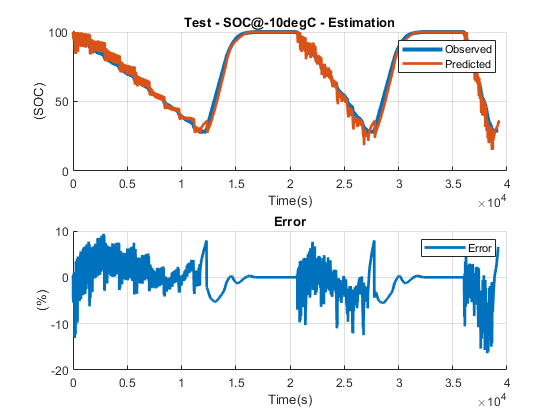

[Minimum_n10degC, idx] = min(cell2mat(E_Test_RMSE_n10degC));
SelectNet =idx;

% SelectNet = 1; % Manual selection

Y_Pred_n10degC = predict(Nets{SelectNet},XT{1, 1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_0degC = predict(Nets{SelectNet},XT{2, 1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_10degC = predict(Nets{SelectNet},XT{3, 1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_25degC = predict(Nets{SelectNet},XT{4, 1}.X,'MiniBatchSize',miniBatchSize);

Error_Test_n10degC = Y_Pred_n10degC(:,N:end-NN)-XT{1, 1}.Y(:,N:end-NN);
Error_Test_0degC = Y_Pred_0degC(:,N:end-NN)-XT{2, 1}.Y(:,N:end-NN);
Error_Test_10degC = Y_Pred_10degC(:,N:end-NN)-XT{3, 1}.Y(:,N:end-NN);
Error_Test_25degC = Y_Pred_25degC(:,N:end-NN)-XT{4, 1}.Y(:,N:end-NN);

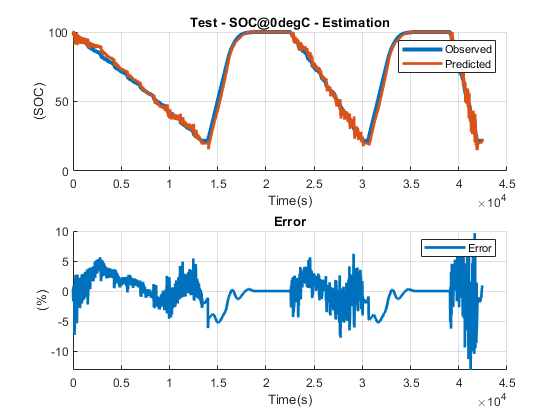


figure
subplot(2,1,1)
grid on
hold all;
plot(XT{1, 1}.Y(:,N:end-NN)*100,'LineWidth',3,'LineStyle','-'); 
plot(Y_Pred_n10degC*100,'LineWidth',2,'LineStyle','-');

legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("Test - SOC@-10degC - Estimation")

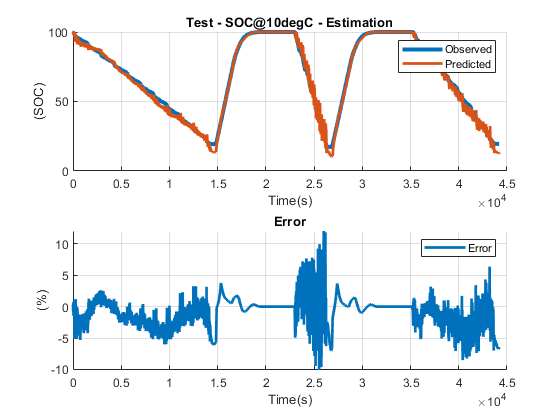

grid on

subplot(2,1,2)
grid on
hold all;
plot((Error_Test_n10degC)*100,'LineWidth',2,'LineStyle','-'); 
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error")  

figure
subplot(2,1,1)
grid on
hold all;
plot(XT{2, 1}.Y(:,N:end-NN)*100,'LineWidth',3,'LineStyle','-'); 
plot(Y_Pred_0degC*100,'LineWidth',2,'LineStyle','-');

legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("Test - SOC@0degC - Estimation")

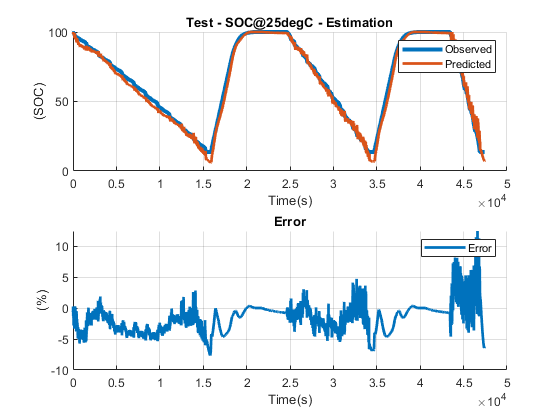

grid on

subplot(2,1,2)
grid on
hold all;
plot((Error_Test_0degC)*100,'LineWidth',2,'LineStyle','-'); 
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error") 

figure
subplot(2,1,1)
grid on
hold all;
plot(XT{3, 1}.Y(:,N:end-NN)*100,'LineWidth',3,'LineStyle','-'); 
plot(Y_Pred_10degC*100,'LineWidth',2,'LineStyle','-');

legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("Test - SOC@10degC - Estimation")

grid on

subplot(2,1,2)
grid on
hold all;
plot((Error_Test_10degC)*100,'LineWidth',2,'LineStyle','-'); 
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error")  

figure
subplot(2,1,1)
grid on
hold all;
plot(XT{4, 1}.Y(:,N:end-NN)*100,'LineWidth',3,'LineStyle','-'); 
plot(Y_Pred_25degC*100,'LineWidth',2,'LineStyle','-');

legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("Test - SOC@25degC - Estimation")
grid on

subplot(2,1,2)
grid on
hold all;
plot((Error_Test_25degC)*100,'LineWidth',2,'LineStyle','-'); 
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error")  

## Functions

The `padSequence` function pads or truncates the sequence in `data.X` to have the specified sequence length and returns the result in a 1-by-1 cell.

function sequence = padSequence(data,sequenceLength)
sequence = data.X;
[C,S] = size(sequence);

if S < sequenceLength
    N=round((sequenceLength/S)*1);
    Pad=repmat(sequence,1,N);  
    padding = Pad(:,1:sequenceLength-S);
    sequence = [sequence padding];
else
    sequence = sequence(:,1:sequenceLength);
end
sequence = {sequence};
end
function sequenceY = padSequenceY(data,sequenceLength)
sequenceY = data.Y;
[C,S] = size(sequenceY);
if S < sequenceLength
    N=round((sequenceLength/S)*1);
    Pad=repmat(sequenceY,1,N);
    padding = Pad(:,1:sequenceLength-S);
    sequenceY = [sequenceY padding];
else
    sequenceY = sequenceY(:,1:sequenceLength);
end
sequenceY = {sequenceY};
end